# Initialization

clear all;

% accel data
accelerometer = load("acc_run2.mat");
% a2 = load("acc_run2.mat");
sampling = accelerometer.samples_per_second;
data_length = length(accelerometer.channels{1}.data);
t = linspace(0, data_length/2, data_length);

% cued data
cued_data = load('1330_2_2021_Jul_13_1526_V_cued_r_time.mat');
cued_data.stimonset = round(cued_data.stimonset * 1000);
cued_data.presstime = round(cued_data.presstime * 1000);

% FFT
fft_raw = zeros(data_length, length(accelerometer.channels));
for i = 1:length(accelerometer.channels)
    fft_raw(:, i) = abs(fft(accelerometer.channels{i}.data)).^2 ./ data_length;
end

f = (1:length(fft_raw)) * sampling / length(fft_raw);

# First plotting

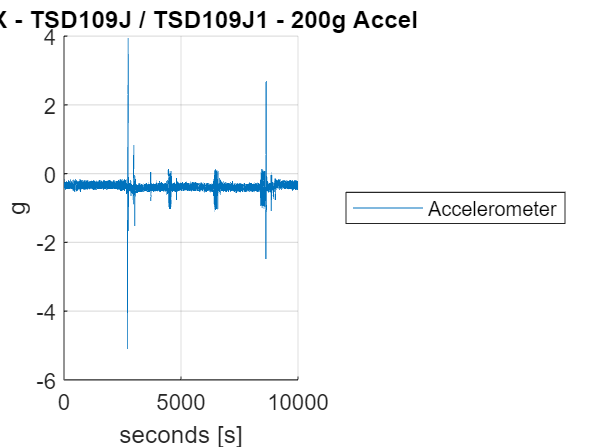

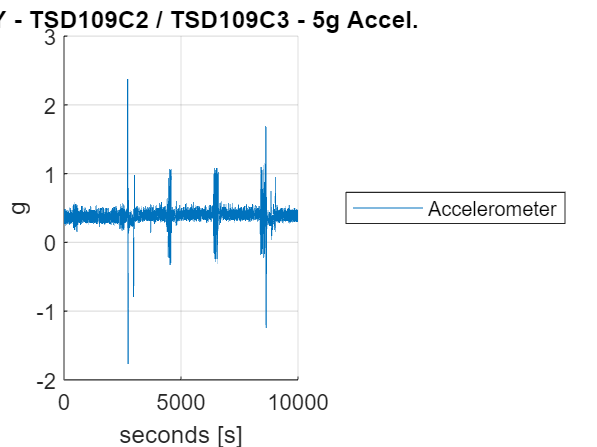

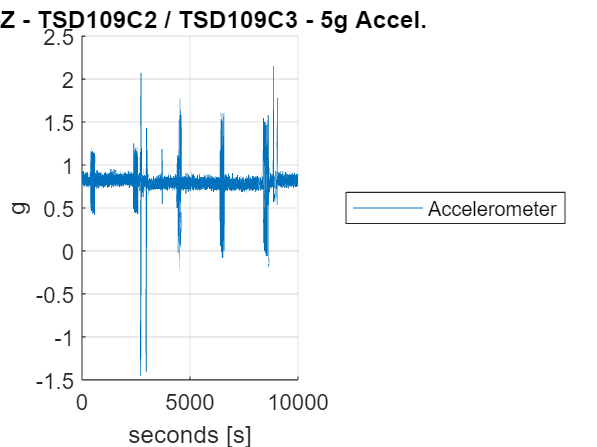

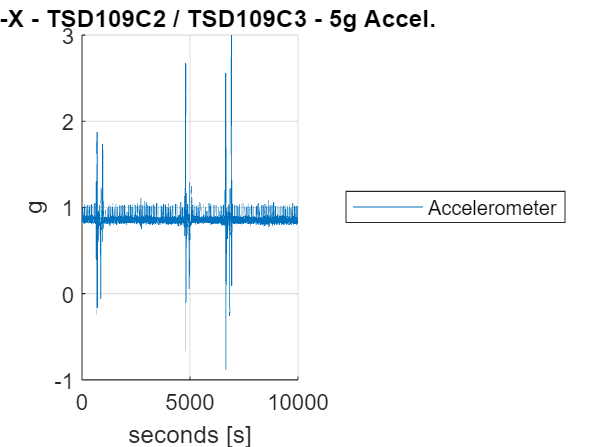

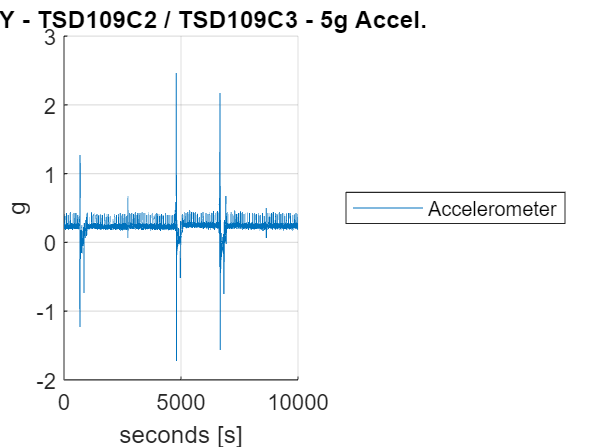

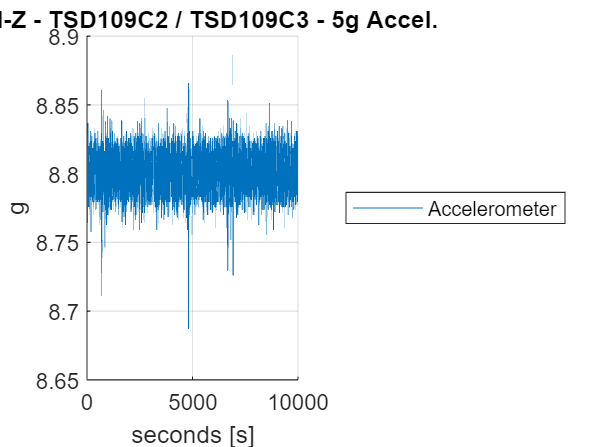

for i = 1:length(accelerometer.channels)
    figure()
    hold on
    plot(t, accelerometer.channels{i}.data)
    hold off
    
    title(accelerometer.channels{i}.name)
    ylabel(accelerometer.channels{i}.units)
    xlabel('seconds [s]')
    xlim([0,1e4])
    grid("on")
    legend("Accelerometer", 'Location','eastoutside')
end  

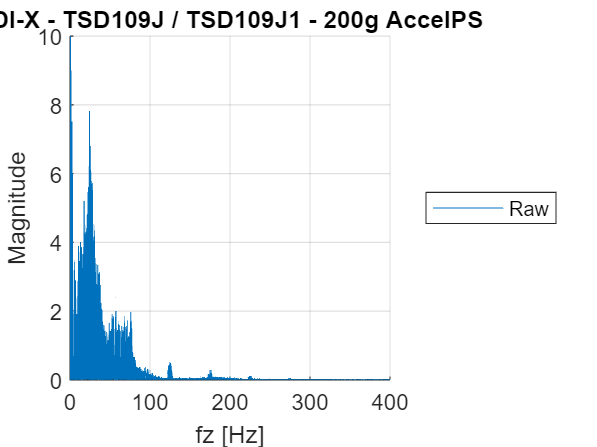

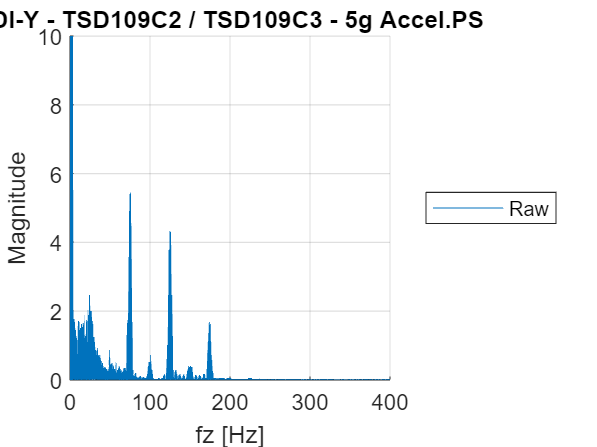

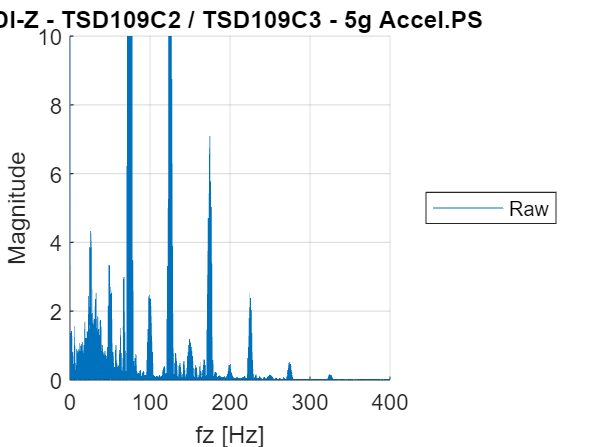

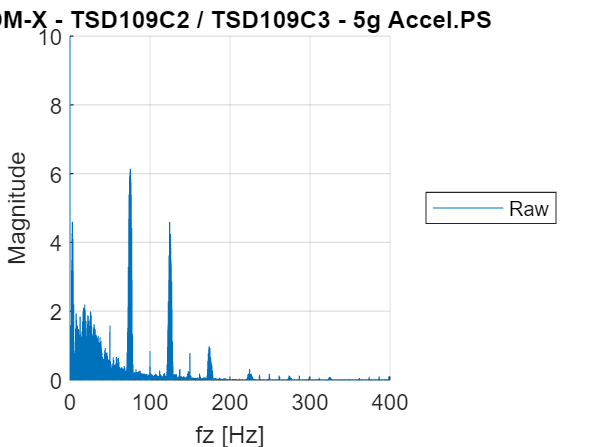

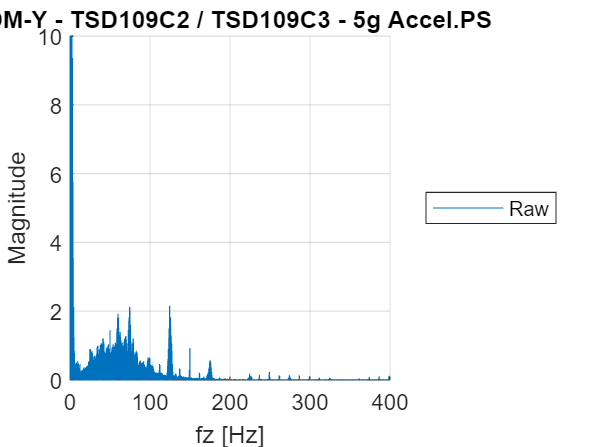

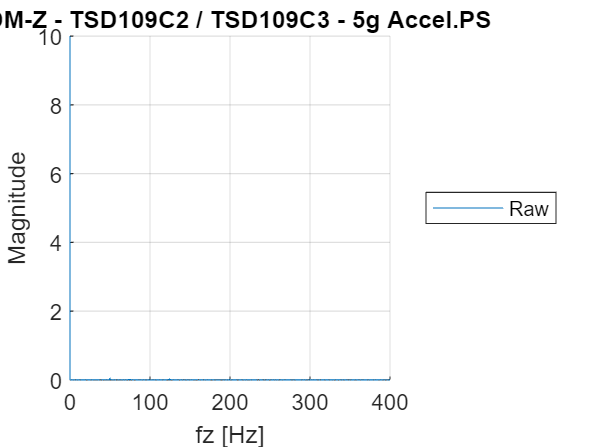


for i = 1:length(accelerometer.channels)
    figure()

    hold on 
    plot(f, fft_raw(:,i))
    hold off

    title(accelerometer.channels{i}.name + "PS")
    ylabel('Magnitude')
    xlabel('fz [Hz]')
    grid("on")
    xlim([0, 400])
    ylim([0, 10])
    legend("Raw", 'Location','eastoutside')
end

# Filtering (isolating the vibration)

% Isolating vibration at 75 nd 175 Hz
cutoff_low = 120; 

cutoff_high = 130; 
filter_order = 5;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

vibration = zeros(data_length, length(accelerometer.channels));
for i = 1:length(accelerometer.channels)
    vibration(:,i) = abs(filtfilt(b, a , accelerometer.channels{i}.data));
end

% Enveloping
filter_order = 3;
cutoff_low = 5;
[b,a] = butter(filter_order, cutoff_low/(sampling/2), 'low');

vibration_envelope = filtfilt(b,a, vibration) * 2;

[v_peaks_fdi, v_peaks_locs_fdi] = findpeaks(vibration_envelope(:,3), 'MinPeakProminence', 0.05);
[v_peaks_adm, v_peaks_locs_adm] = findpeaks(vibration_envelope(:,4), 'MinPeakProminence', 0.05);

# Isolating the movement

cutoff_low = 1; 
cutoff_high = 10; % around maximum of non trained human movement
filter_order = 1;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

movement = zeros(data_length, length(accelerometer.channels));
for i = 1:length(accelerometer.channels)
    movement(:,i) = filtfilt(b, a , accelerometer.channels{i}.data);
end

filter_order = 3;
cutoff_low = 5;
[b,a] = butter(filter_order, cutoff_low/(sampling/2), 'low');

movement_envelope = abs(filtfilt(b,a, abs(movement)));

[m_peaks_fdi, m_peaks_locs_fdi] = findpeaks(movement_envelope(:,1), 'MinPeakProminence', 0.05);
[m_peaks_adm, m_peaks_locs_adm] = findpeaks(movement_envelope(:,4), 'MinPeakProminence', 0.05);

m_borders_fdi = getBorders(movement_envelope(:,1), m_peaks_locs_fdi, m_peaks_fdi);
m_borders_adm = getBorders(movement_envelope(:,4), m_peaks_locs_adm, m_peaks_adm);

# Remove movement detection from vibration

indexes = getVibrationsInMovement(v_peaks_locs_fdi, m_borders_fdi);
v_peaks_fdi(indexes) = [];
v_peaks_locs_fdi(indexes) = [];

indexes = getVibrationsInMovement(v_peaks_locs_adm, m_borders_adm);
v_peaks_adm(indexes) = [];
v_peaks_locs_adm(indexes) = [];

v_borders_fdi = getBorders(vibration_envelope(:,3), v_peaks_locs_fdi, v_peaks_fdi);
v_borders_adm = getBorders(vibration_envelope(:,4), v_peaks_locs_adm, v_peaks_adm);

# Segmentation

trial_onset = zeros(length(accelerometer.event_markers),1); % 240 trials from 0 
for i = 1:length(accelerometer.event_markers)
    trial_onset(i) = accelerometer.event_markers{i}.sample_index;
end
% cued_data.triallist corresponds to 240 trials

## Vibration and movement segmentation

vibration_onsets = sort([v_borders_fdi(:,1)', v_borders_adm(:,1)']);
% if there are two too close need to get the first one bc it's a vibration
vibration_onsets(diff(vibration_onsets) < 3000)


ans =

  1×0 empty double row vector



vibration_onsets(diff(vibration_onsets) < 3000) = [];

% vibration 1 -> FDI, 2 -> ADM, 0 -> not detected
vibration_onset_finger = zeros(length(vibration_onsets),1);
% press_finger 1 -> FDI, 2 -> ADM, 0 -> not detected
movement_finger = zeros(length(trial_onset),1);

for i = 1:length(trial_onset)
    start = trial_onset(i);
    if i < length(trial_onset)
        finish = trial_onset(i+1);
    else
        finish = data_length;
    end

    % movement
    if ~isempty(m_peaks_locs_fdi(m_peaks_locs_fdi > start & m_peaks_locs_fdi < finish))
        movement_finger(i) = 1;
    end
    if ~isempty(m_peaks_locs_adm(m_peaks_locs_adm > start & m_peaks_locs_adm < finish))
        movement_finger(i) = 2;
    end
    if ~isempty(m_peaks_locs_fdi(m_peaks_locs_fdi > start & m_peaks_locs_fdi < finish)) && ~isempty(m_peaks_locs_adm(m_peaks_locs_adm > start & m_peaks_locs_adm < finish))
        movement_finger(i) = 0;
    end
    
    % vibration
    current_vibration = vibration_onsets(vibration_onsets > start & vibration_onsets < finish);
    if isempty(current_vibration)
        vibration_onset_finger(i) = 0;
        continue;
    end
    if ismember(current_vibration, v_borders_fdi)
        vibration_onset_finger(i) = 1;
        continue;
    end
    if ismember(current_vibration, v_borders_adm)
        vibration_onset_finger(i) = 2;
        continue;
    end
end

## Determining trial type

test_type = zeros(length(trial_onset),1); % 0 if not detected
for i = 1:length(trial_onset)
    if vibration_onset_finger(i) == 0 || movement_finger(i) == 0
        test_type(i) = 0;
    end
    if vibration_onset_finger(i) == 1 && movement_finger(i) == 1
        test_type(i) = 3;
    end
    if vibration_onset_finger(i) == 2 && movement_finger(i) == 1
        test_type(i) = 2;
    end
    if vibration_onset_finger(i) == 1 && movement_finger(i) == 2
        test_type(i) = 1;
    end
    if vibration_onset_finger(i) == 2 && movement_finger(i) == 2
        test_type(i) = 4;
    end
end

## Accuracy check

t1_index = find(cued_data.triallist == 1);
t2_index = find(cued_data.triallist == 2);
t3_index = find(cued_data.triallist == 3);
t4_index = find(cued_data.triallist == 4);

disp("T1: " + (length(find(test_type(t1_index) == 1))) / (length(test_type(t1_index))) * 100 + "%")

T1: 78.3333%


disp("T2: " + (length(find(test_type(t2_index) == 2))) / (length(test_type(t2_index))) * 100 + "%")

T2: 81.6667%


disp("T3: " + (length(find(test_type(t3_index) == 3))) / (length(test_type(t3_index))) * 100 + "%")

T3: 91.6667%


disp("T4: " + (length(find(test_type(t4_index) == 4))) / (length(test_type(t4_index))) * 100 + "%")

T4: 71.6667%


# RT correlation

TODO: try to see if it works for run 2 too

rt_accelerometer = zeros(length(trial_onset),1);
for i = 1:length(trial_onset)
        start = trial_onset(i);
    if i < length(trial_onset)
        finish = trial_onset(i+1);
    else
        finish = data_length;
    end

    % vibration
    current_vibration = vibration_onsets(vibration_onsets > start & vibration_onsets < finish);
    if isempty(current_vibration)
        rt_accelerometer(i) = -1;
        continue;
    end

    % movement  
    current_movement_fdi = [];
    current_movement_adm = [];
    if ~isempty(m_peaks_locs_fdi(m_peaks_locs_fdi > start & m_peaks_locs_fdi < finish))
        current_movement_fdi = min(m_peaks_locs_fdi(m_peaks_locs_fdi > start & m_peaks_locs_fdi < finish));
    end
    if ~isempty(m_peaks_locs_adm(m_peaks_locs_adm > start & m_peaks_locs_adm < finish))
        current_movement_adm = min(m_peaks_locs_adm(m_peaks_locs_adm > start & m_peaks_locs_adm < finish));
    end
    if isempty(current_movement_adm)
        if isempty(current_movement_fdi)
            rt_accelerometer(i) = -1;
            continue;
        end
        current_movement = current_movement_fdi;
    else
        if ~isempty(current_movement_fdi)
            current_movement = min(current_movement_fdi, current_movement_adm);
            continue;
        end
        current_movement = current_movement_adm;
    end

    % Calculate rt in ms
    rt_accelerometer(i) = abs(current_movement - current_vibration) / 2;
end

## Removing incaccurate guesses

corrected_test_type = [];
corrected_rt = [];
corrected_t1_index = [];
corrected_t2_index = [];
corrected_t3_index = [];
corrected_t4_index = [];

for i = 1:length(test_type)
    if (ismember(i, t1_index) && test_type(i) == 1) || (ismember(i, t2_index) && test_type(i) == 2) || ...
            (ismember(i, t3_index) && test_type(i) == 3) || (ismember(i, t4_index) && test_type(i) == 4) ...
            && (rt_accelerometer(i) > 0)
        % corrected_test_type = [corrected_test_type, test_type(i)];
        % corrected_rt = [corrected_rt, rt_accelerometer(i)];
        if ismember(i, t1_index)
            corrected_t1_index = [corrected_t1_index, i];
        end
        if ismember(i, t2_index)
            corrected_t2_index = [corrected_t2_index, i];
        end
        if ismember(i, t3_index)
            corrected_t3_index = [corrected_t3_index, i];
        end
        if ismember(i, t4_index)
            corrected_t4_index = [corrected_t4_index, i];
        end
    end
end
length(test_type)

ans = 240

length(corrected_t1_index) + length(corrected_t2_index) + length(corrected_t3_index) + length(corrected_t4_index)

ans = 194

# Comparing reponse box with guesses

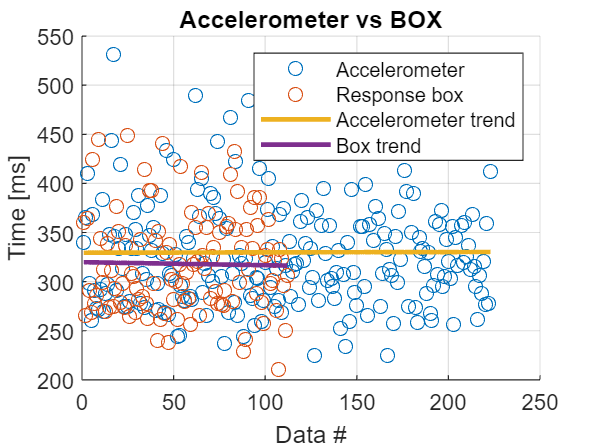

x_acc = linspace(1,length(rt_accelerometer(rt_accelerometer > 0)),length(rt_accelerometer(rt_accelerometer > 0)));
x_box = linspace(1,length(cued_data.presstime(cued_data.presstime ~= 99000)),length(cued_data.presstime(cued_data.presstime ~= 99000)));

p_acc = polyfit(x_acc, rt_accelerometer(rt_accelerometer > 0), 1);
fit_acc = polyval(p_acc, x_acc);

p_box = polyfit(x_box, cued_data.presstime(cued_data.presstime ~= 99000), 1);
fit_box = polyval(p_box, x_box);

figure()

hold on
plot(rt_accelerometer(rt_accelerometer > 0), "o")
plot(cued_data.presstime(cued_data.presstime ~= 99000), 'o')
plot(fit_acc, 'LineWidth', 2)
plot(fit_box, 'LineWidth', 2)
hold off

legend("Accelerometer", "Response box", "Accelerometer trend", "Box trend")
xlabel("Data #")
ylabel("Time [ms]")
title("Accelerometer vs BOX")
grid('on')

temp = rt_accelerometer(rt_accelerometer > 0);
data1 = temp(1:length(cued_data.presstime(cued_data.presstime ~= 99000)))';
data2 = cued_data.presstime(cued_data.presstime ~= 99000)';
R = corr(data1', data2)

R = 0.0331

# Summary statistics

tests = {corrected_t1_index; corrected_t2_index;...
    corrected_t3_index; corrected_t4_index};

for i = 1:length(tests(:,1))
    temp = cell2mat(tests(i));
    disp("Test type: " + i)

    disp("---------------------------------")
    disp("Max: " + max(rt_accelerometer(temp)))
    disp("Min: " + min(rt_accelerometer(temp))) 
    disp("Mean: " + mean(rt_accelerometer(temp)))
    disp("Median: " + median(rt_accelerometer(temp)))
    disp("Standard deviation: " + std(rt_accelerometer(temp)))
    disp("---------------------------------")
end

Test type: 1


---------------------------------


Max: 489.5


Min: 244


Mean: 345.7234


Median: 333.5


Standard deviation: 59.3991


---------------------------------


Test type: 2


---------------------------------


Max: 434


Min: 268.5


Mean: 339.6633


Median: 346


Standard deviation: 39.3983


---------------------------------


Test type: 3


---------------------------------


Max: 443.5


Min: 224.5


Mean: 305.4636


Median: 302


Standard deviation: 48.8228


---------------------------------


Test type: 4


---------------------------------


Max: 531


Min: 245


Mean: 343.3953


Median: 326.5


Standard deviation: 66.9367


---------------------------------



corrected_t1_index = [];
corrected_t2_index = [];
corrected_t3_index = [];
corrected_t4_index = [];

disp('################')

################


disp('BOX:')

BOX:


disp('################')

################



for i = 1:length(cued_data.presstime)
    if cued_data.presstime(i) == 99000
        continue;
    end
    if cued_data.triallist(i) == 1
        corrected_t1_index = [corrected_t1_index, i];
    end
    if cued_data.triallist(i) == 2
        corrected_t2_index = [corrected_t2_index, i];
    end
    if cued_data.triallist(i) == 3
        corrected_t3_index = [corrected_t3_index, i];
    end
    if cued_data.triallist(i) == 4
        corrected_t4_index = [corrected_t4_index, i];
    end
end
tests = {corrected_t1_index; corrected_t2_index;...
    corrected_t3_index; corrected_t4_index};
for i = 1:length(tests(:,1))
    temp = cell2mat(tests(i));
    disp("Test type: " + i)

    disp("---------------------------------")
    disp("Max: " + max(cued_data.presstime(temp)))
    disp("Min: " + min(cued_data.presstime(temp))) 
    disp("Mean: " + mean(cued_data.presstime(temp)))
    disp("Median: " + median(cued_data.presstime(temp)))
    disp("Standard deviation: " + std(cued_data.presstime(temp)))
    disp("---------------------------------")
end

Test type: 1


---------------------------------


Max: 357


Min: 238


Mean: 276.8


Median: 276


Standard deviation: 33.3227


---------------------------------


Test type: 2


---------------------------------


Max: 449


Min: 256


Mean: 342.1136


Median: 341


Standard deviation: 47.5048


---------------------------------


Test type: 3


---------------------------------


Max: 445


Min: 211


Mean: 306.8571


Median: 295.5


Standard deviation: 48.3959


---------------------------------


Test type: 4


---------------------------------


Max: 317


Min: 299


Mean: 308


Median: 308


Standard deviation: 12.7279


---------------------------------
